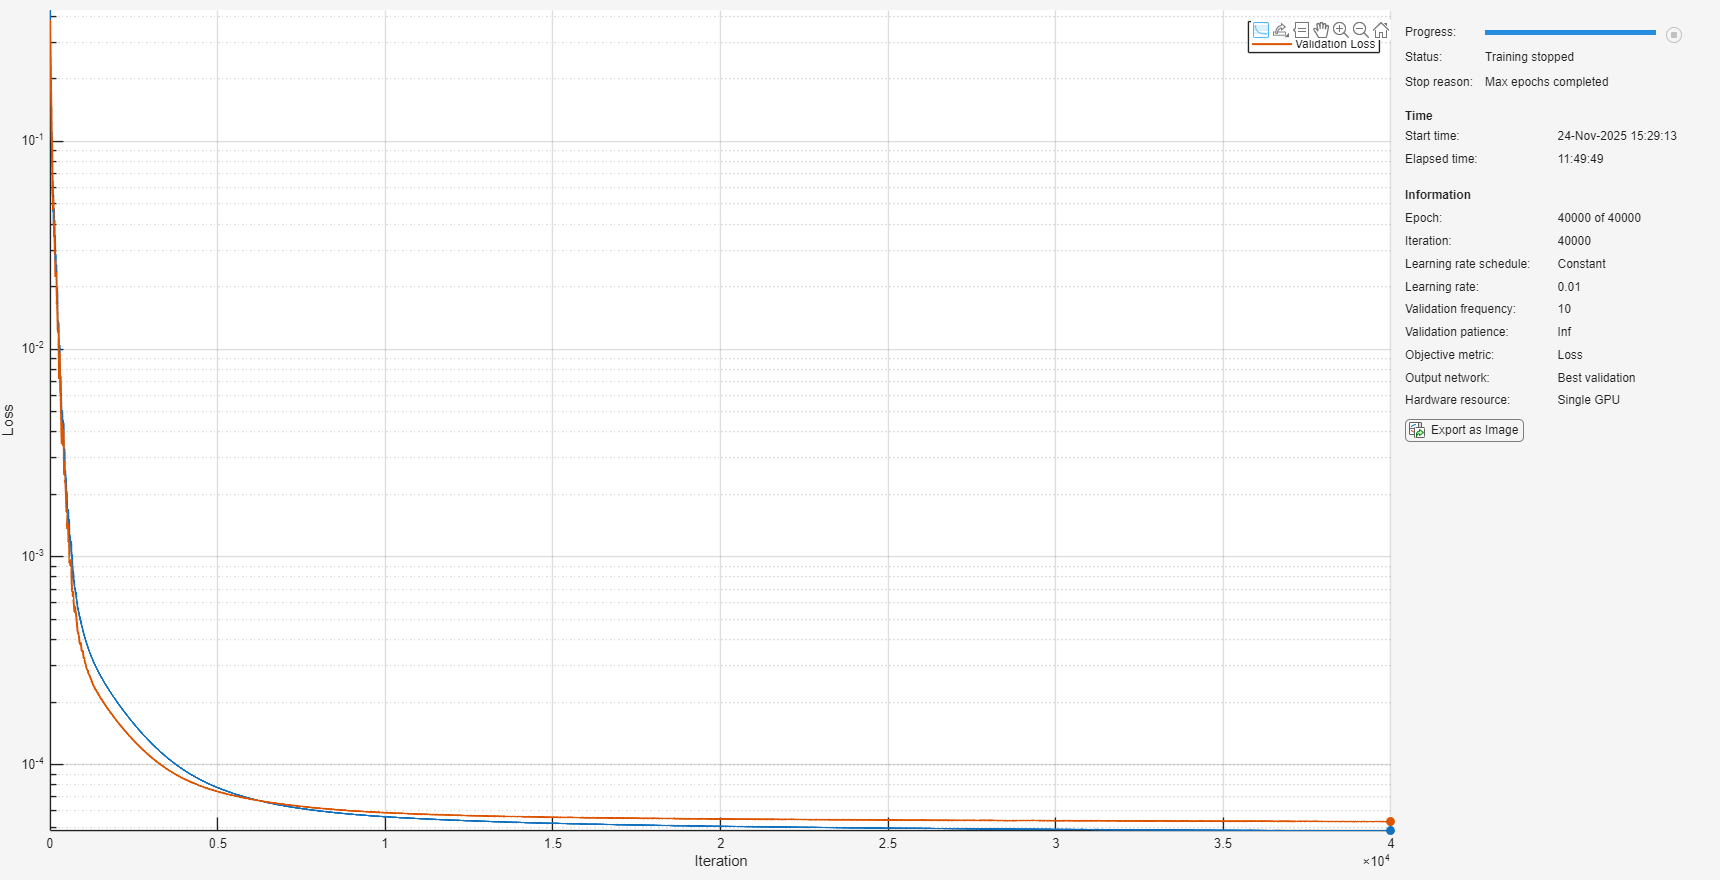

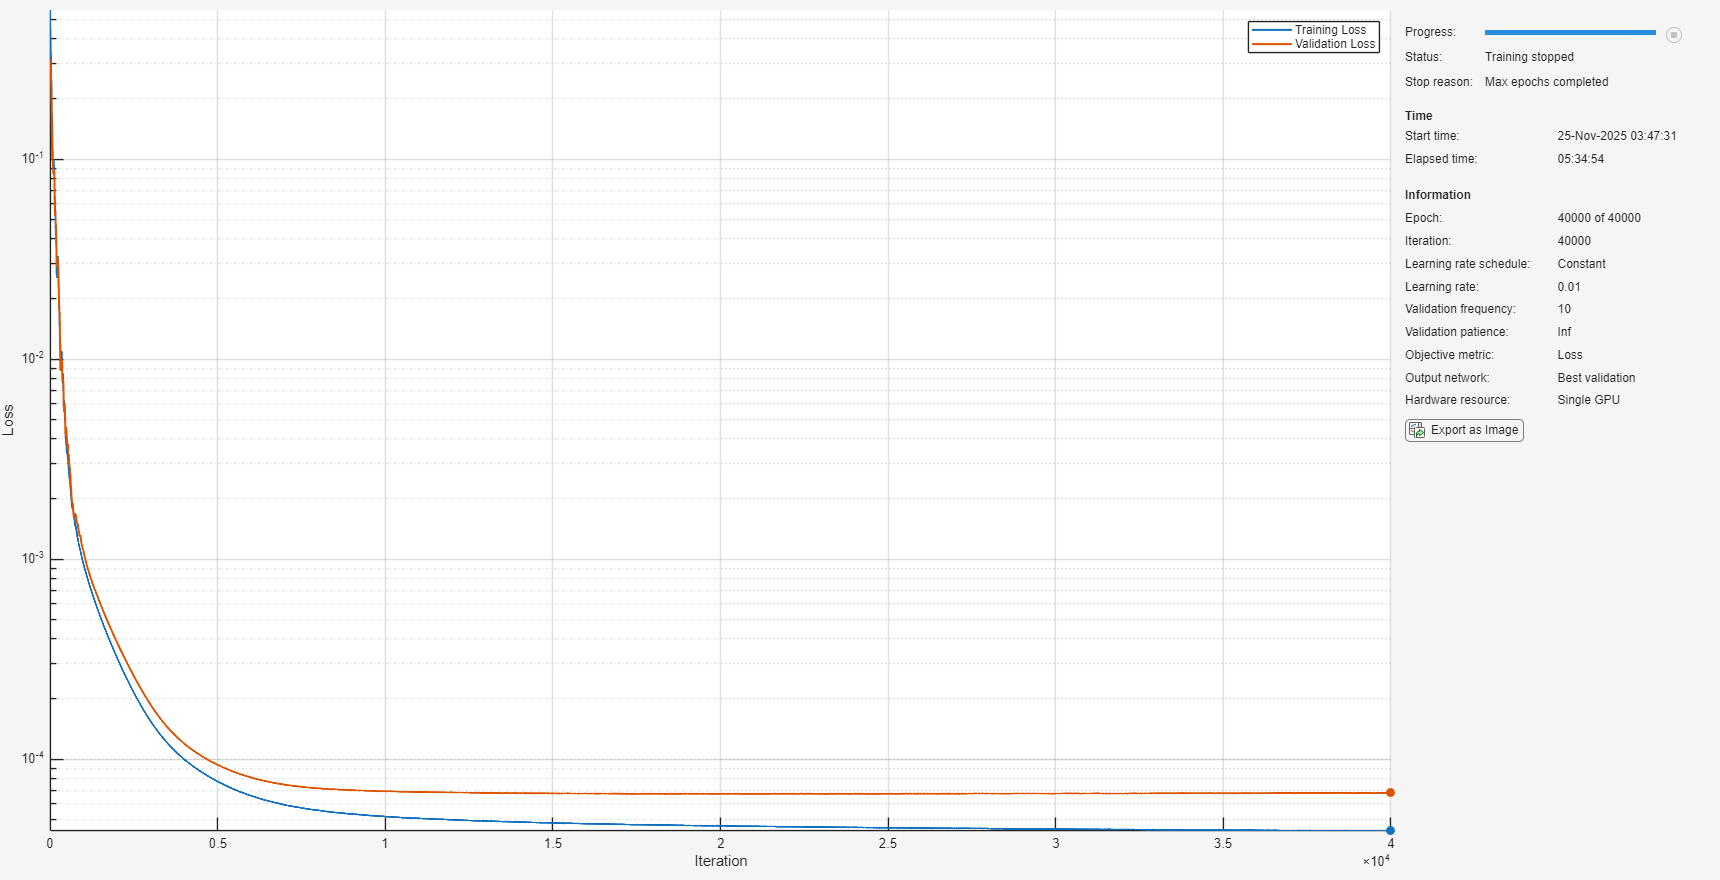

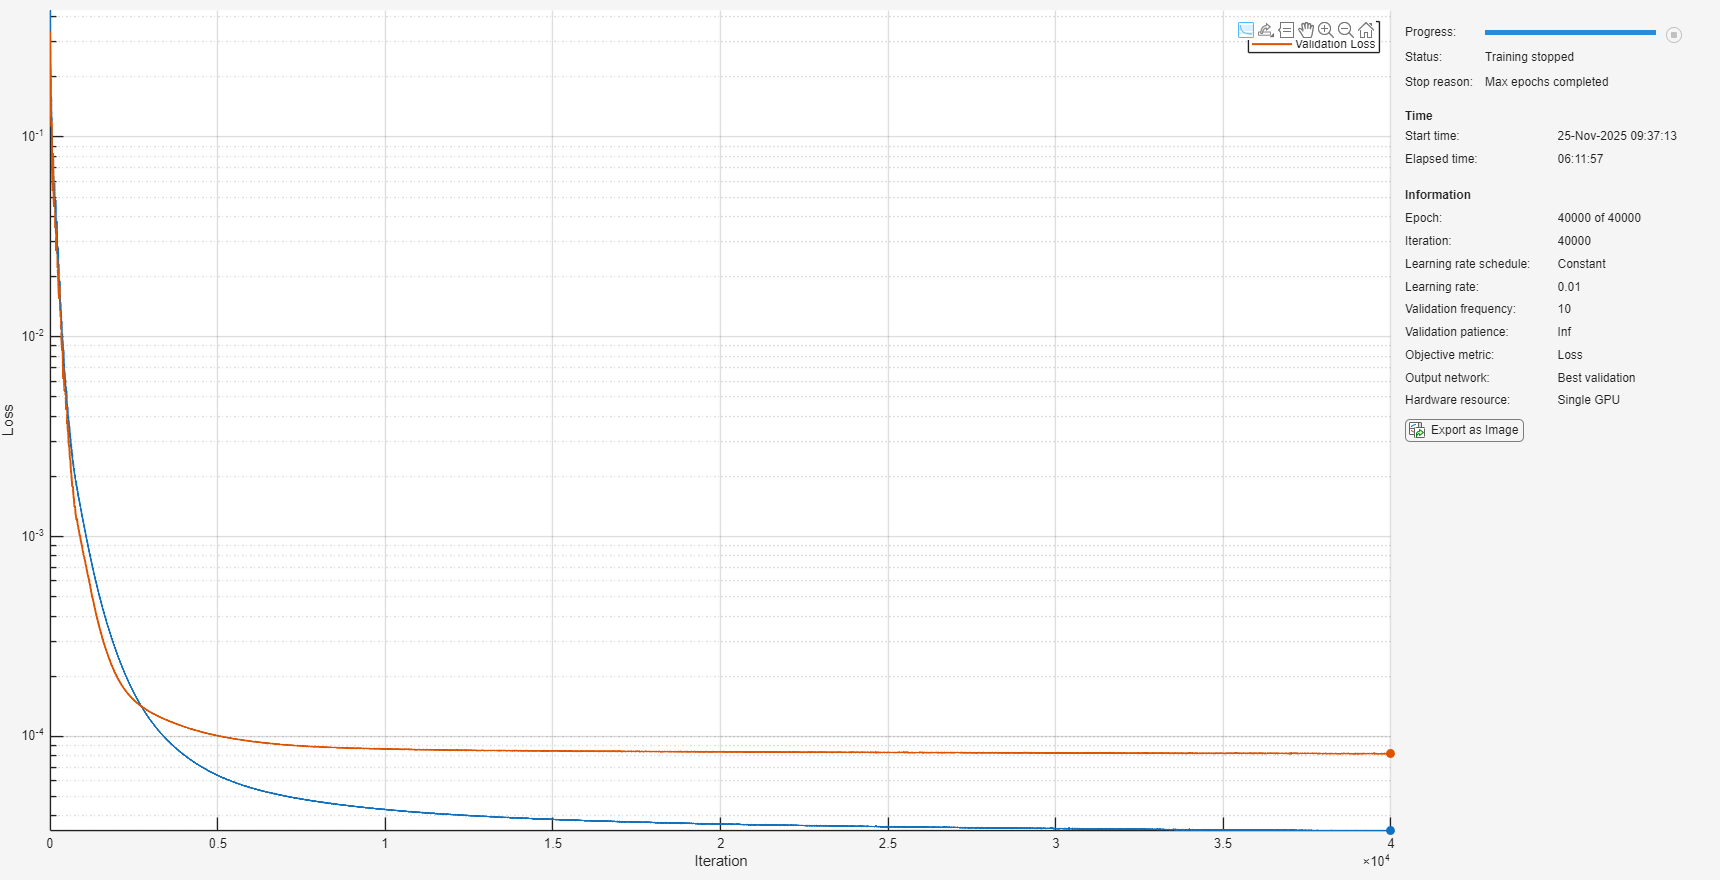

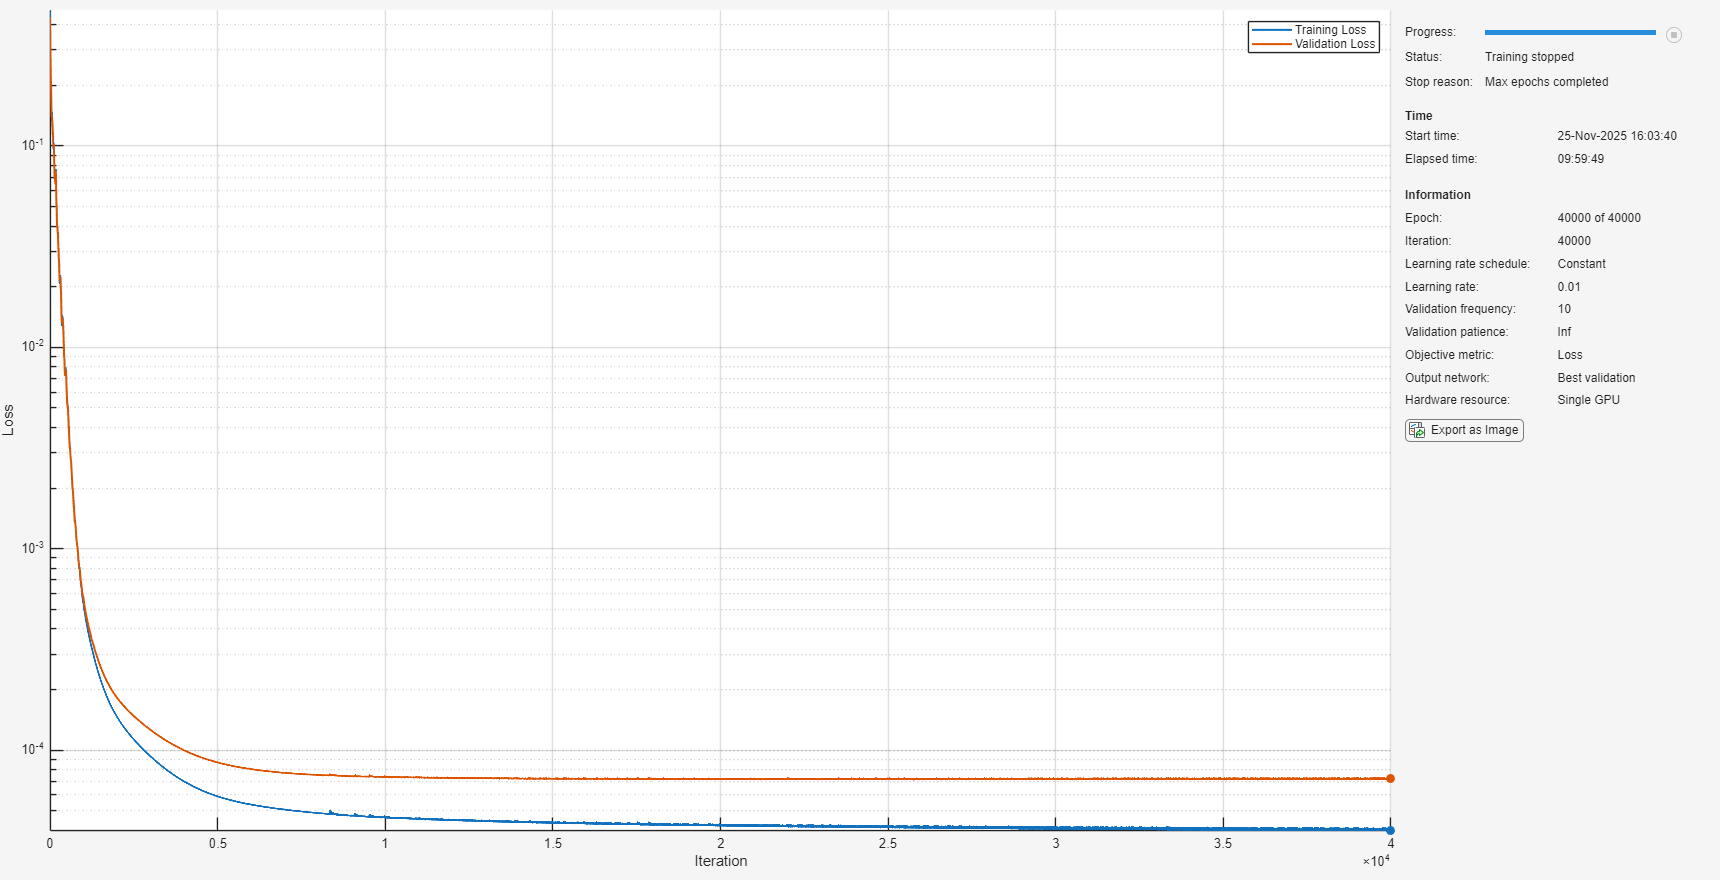

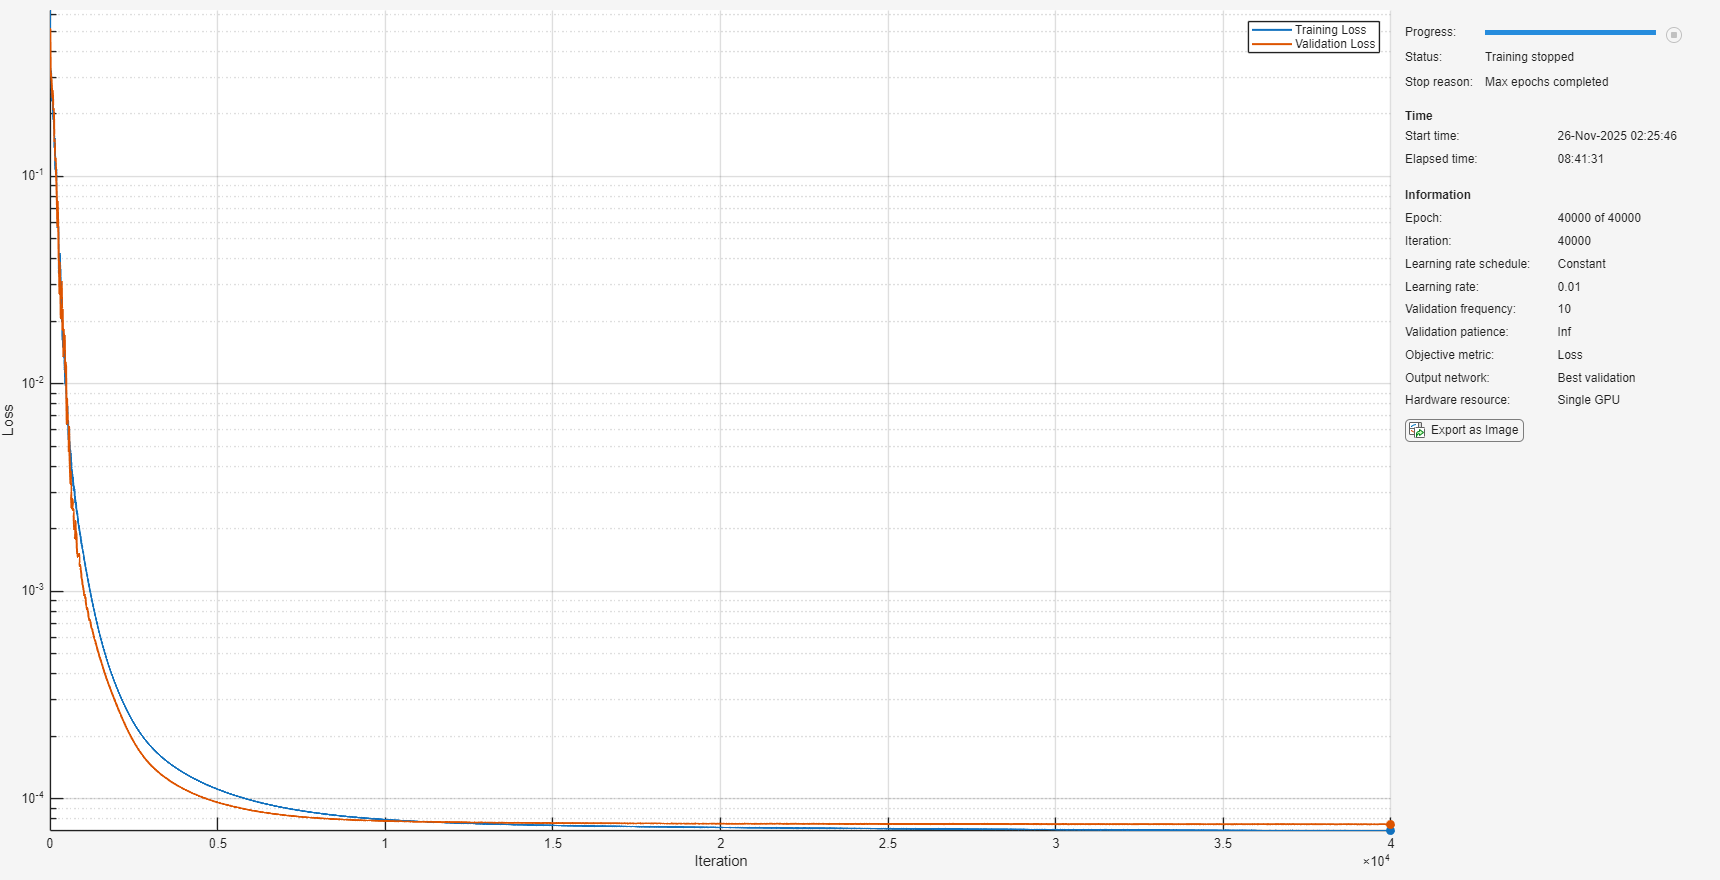

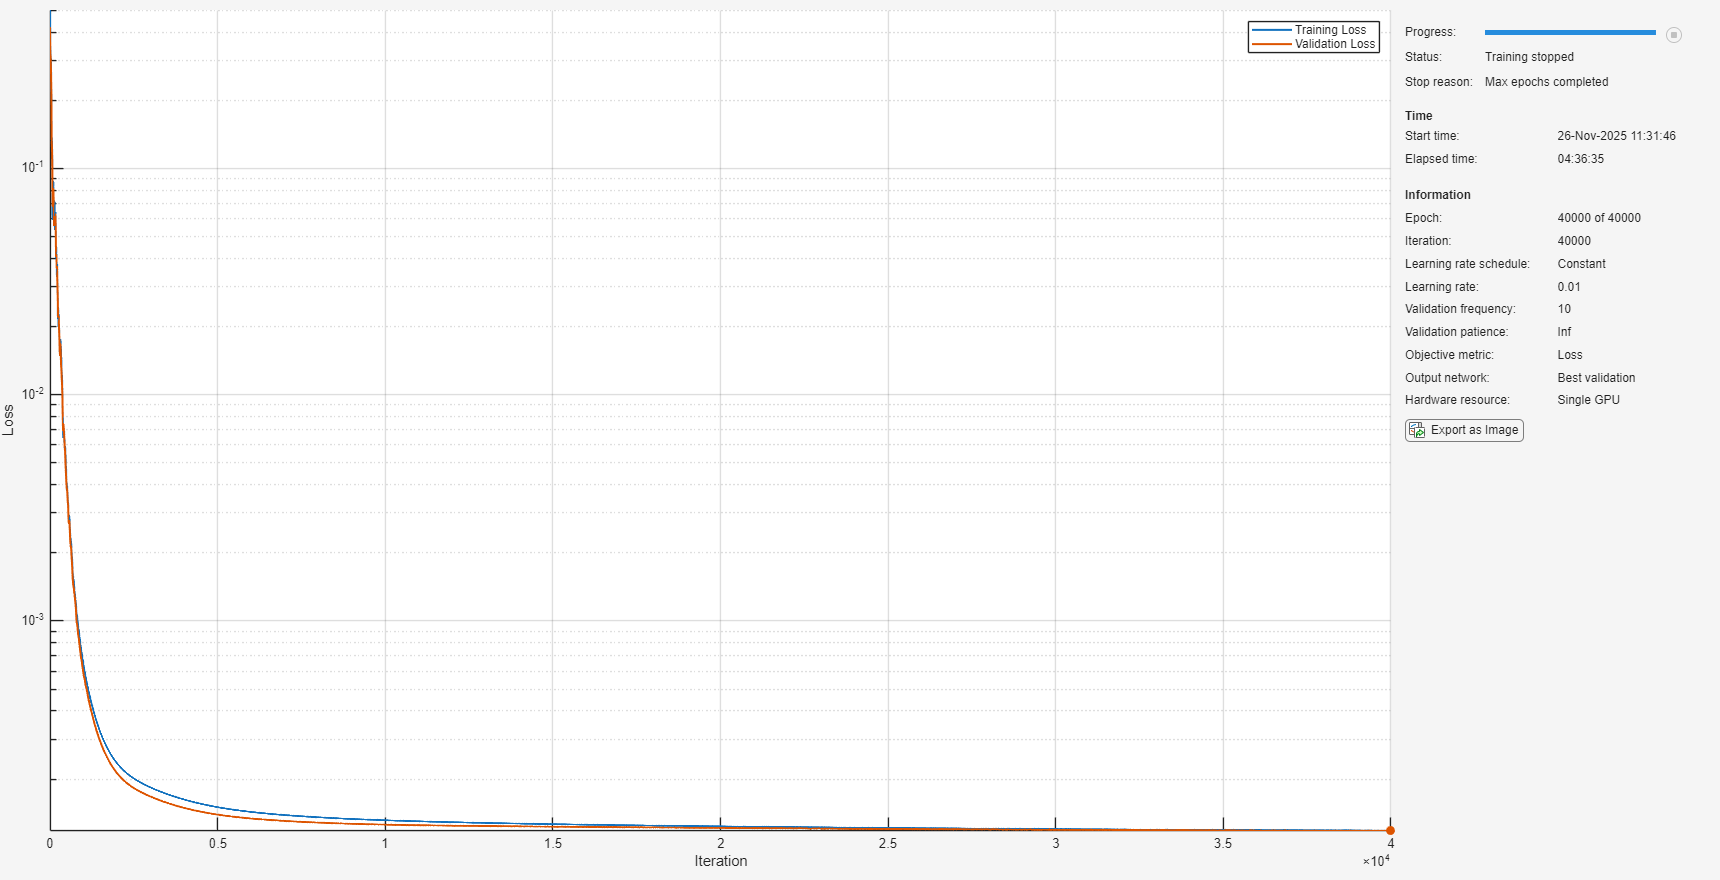

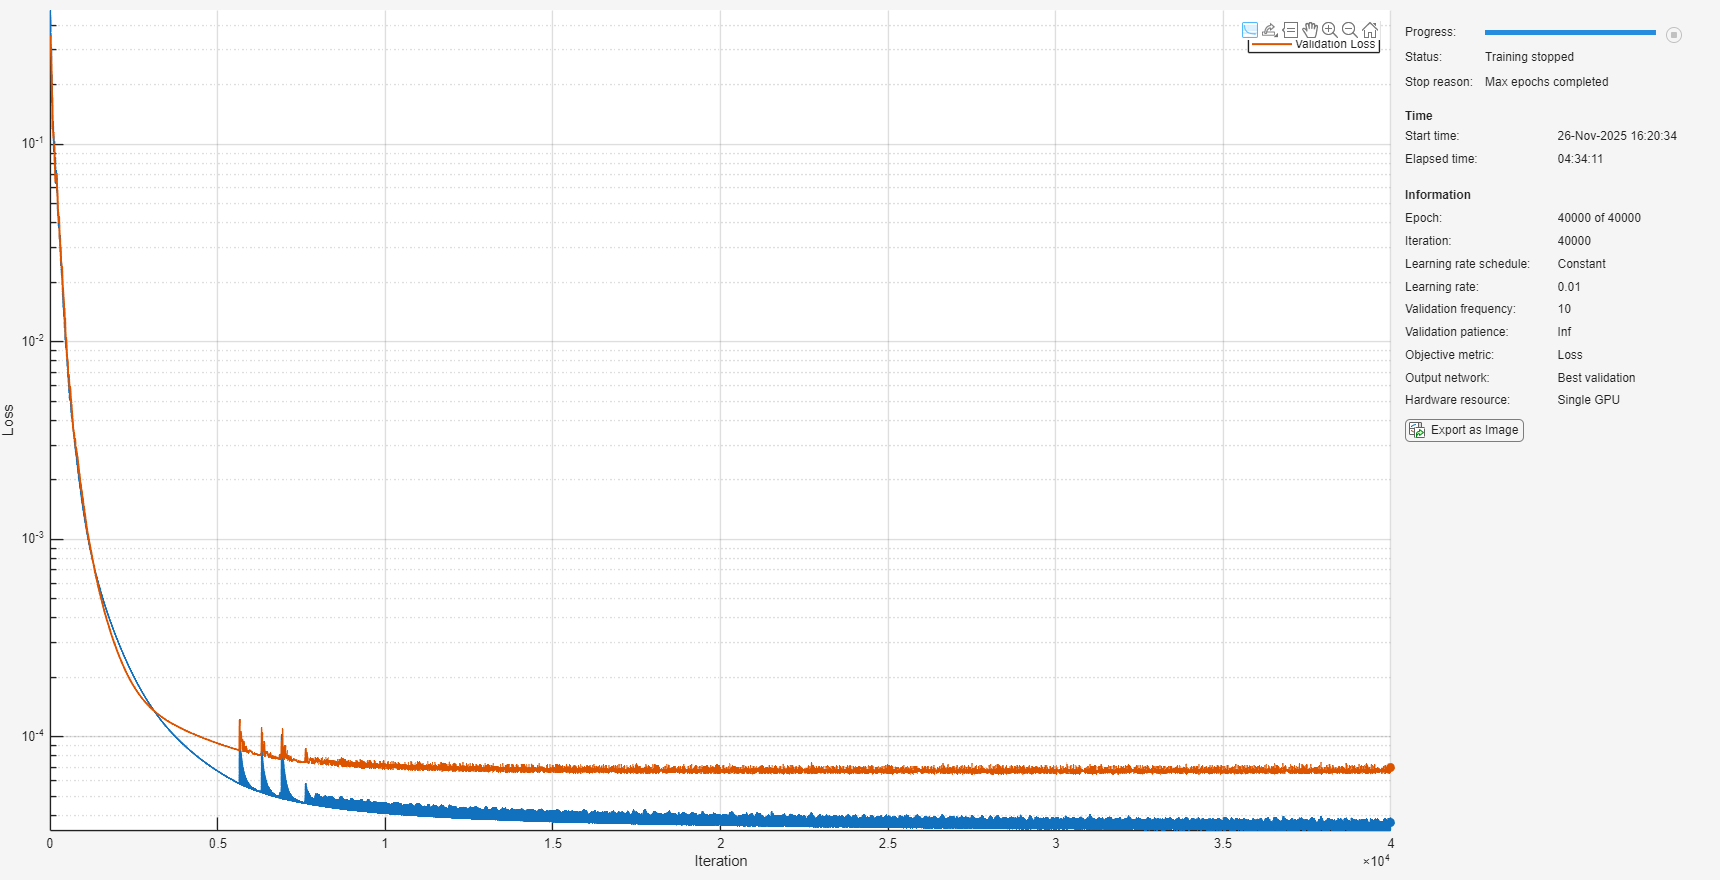

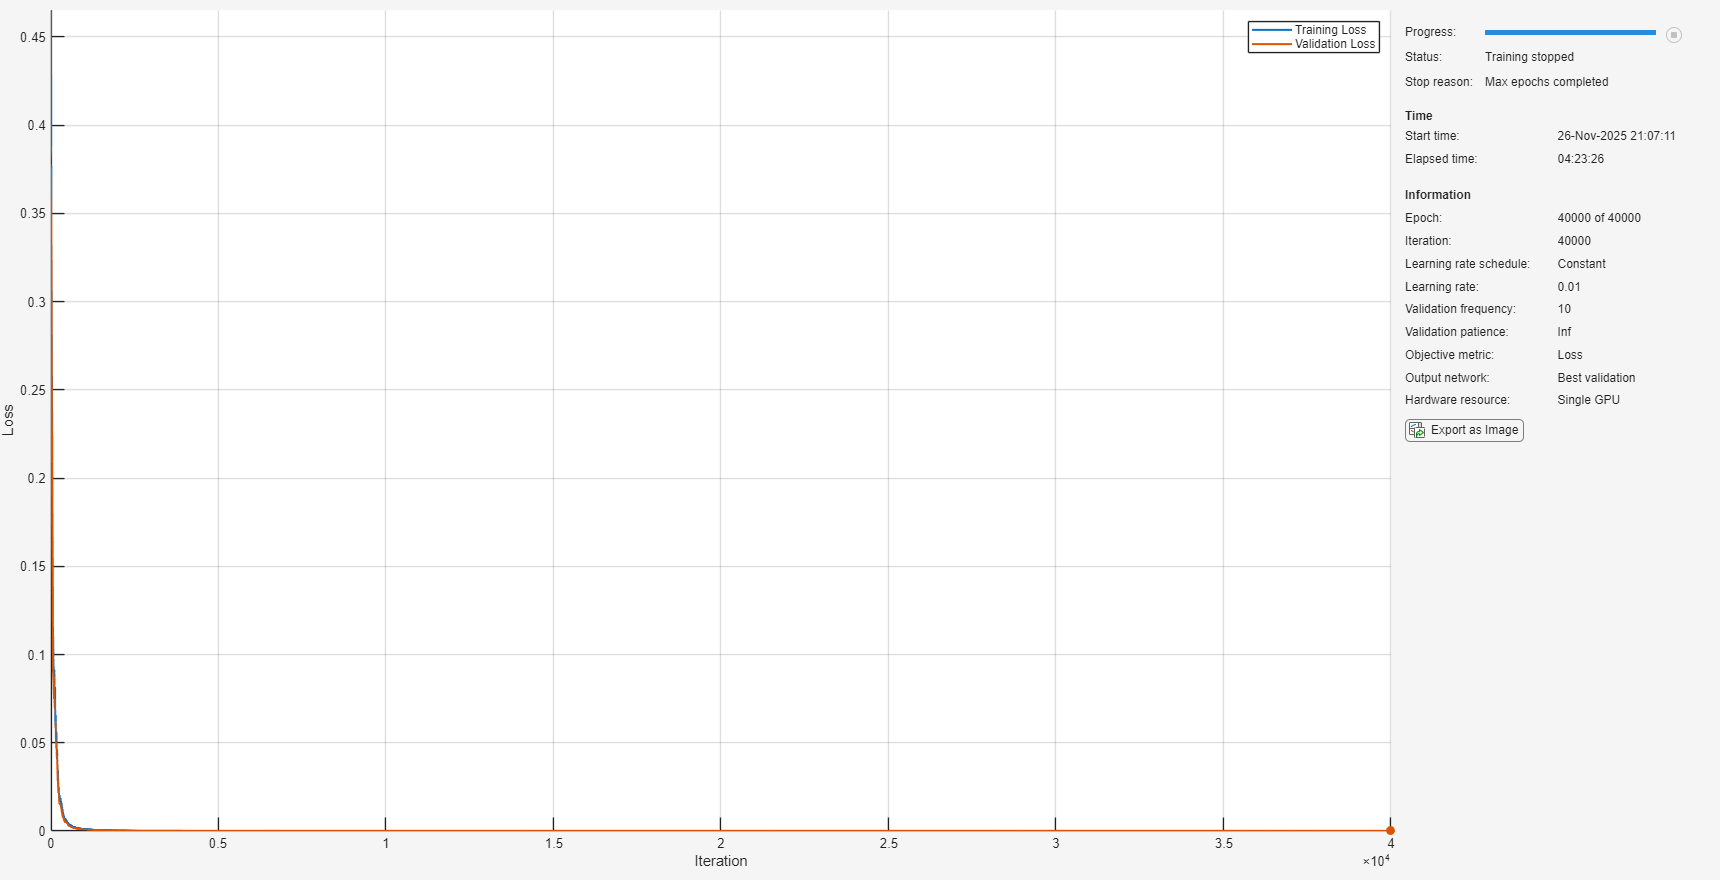

% -----------------------------------------------------------------------
% Script for training a network on dynamical system data and evaluating
% closed-loop performance.
%
% Requirements:
%   • int_dyn.m
%   • extractTimeDelayedInputs.m
%   • extractTimeDelayedInputsFeedback.m
%   • customWeights1_git.m, customWeights2_git.m, customWeights3_git.m
%
% Usage:
%   runDynamics(ii, perturbationScale)
%     ii               Index in dynamics_list.xlsx:
%                        • Lorenz     = 5
%                        • Sprott B    = 8
%                        • Sprott C    = 9
%                        • Sprott S    = 25
%                        • Rikitake    = 32
%                        • MO0         = 34
%                        • MO5         = 39
%                        • MO7         = 41
%                        • MO13        = 47
%     perturbationScale Relative scale of perturbation on initial state
%                      (default: 0.01)
%

for ii = [5,8,9,25,32,34,39,41,47] %Lorenz system

perturbationScale = 0.01; %size of deviation for closed loop test from training IC


%% 1. Setup
clc; clearvars -except ii perturbationScale; close all;
dyn = readtable('dynamics_list.xlsx');

% Extract system parameters
dynamicsName = string(dyn{ii, 1});        % name
ic            = dyn{ii, 4:6}';            % initial condition vector
d             = dyn{ii, 2};               % system dimension

%% 2. Simulate True Dynamics for Training
tSpan = [0, 5000];
[tTrain, xTrue] = ode45(@(t,y) int_dyn(y, dynamicsName, 0,0,0,'Simulate'), tSpan, ic(1:d));
xTrue = normalize(xTrue)/sqrt(size(xTrue,2));

%% 3. Plot Training Time Series & Phase Plane
figure('Name','Training Dynamics');
subplot(2,1,1);
plot(tTrain, xTrue, 'LineWidth', 1);
title('True Time Series'); xlabel('Time'); ylabel('State');
if size(xTrue,2) > 1
    subplot(2,1,2);
    plot(xTrue(:,1), xTrue(:,2), 'LineWidth', 1);
    title('Phase Plot (Channel 1 vs 2)'); xlabel('x_1'); ylabel('x_2');
end

%% 4. Prepare Data for Training
inputDelay = 1;
[inp, tgt] = extractTimeDelayedInputs(xTrue, inputDelay);
X = dlarray(inp,'CTB'); Y = dlarray(tgt,'CTB');
N = size(X,3);
idx = floor(0.8*N);
XTrain = X(:,:,1:idx); YTrain = Y(:,:,1:idx);
XVal   = X(:,:,idx+1:end); YVal   = Y(:,:,idx+1:end);

%% 5. Define & Train NAR Network
layers = [
    sequenceInputLayer(size(XTrain,1))
    fullyConnectedLayer(16000,'WeightLearnRateFactor',0, 'WeightsInitializer',@customWeights1_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(16000,'WeightLearnRateFactor',0, 'WeightsInitializer',@customWeights2_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(size(xTrue,2),'Name','output','WeightLearnRateFactor',0,'WeightsInitializer',@customWeights3_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    ];
net = dlnetwork(layerGraph(layers));

options = trainingOptions('adam', ...
    MaxEpochs=40000, InitialLearnRate=0.01, MiniBatchSize=size(XTrain,3), ...
    Shuffle='never', Plots='training-progress', ValidationData={XVal,YVal}, ...
    ValidationFrequency=10, Verbose=0, L2Regularization=0, ...
    GradientDecayFactor=0.99, SquaredGradientDecayFactor=0.999, Epsilon=5e-6);

[net, trainingInfo] = trainnet(XTrain, YTrain, net, 'mse', options);


%% 6. Closed-Loop Test with Perturbed Initial Condition
icTest = ic + perturbationScale * randn(size(ic));  % random perturbation
[~, xTestTrue] = ode45(@(t,y) int_dyn(y, dynamicsName, 0,0,0,'Simulate'), 5*tSpan, icTest(1:d));
xTestTrue = normalize(xTestTrue)/sqrt(size(xTestTrue,2));

% Initialize prediction
xPred = xTestTrue(1:inputDelay, :);
for k = 1:(size(xTestTrue,1)-inputDelay)
    Xf = extractTimeDelayedInputsFeedback(xPred, inputDelay);
    yP = predict(net, Xf(:,end)');
    xPred = [xPred; yP];
end


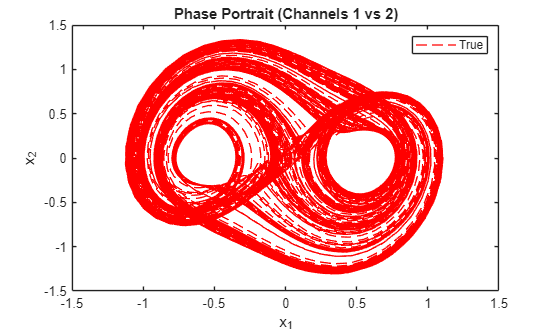

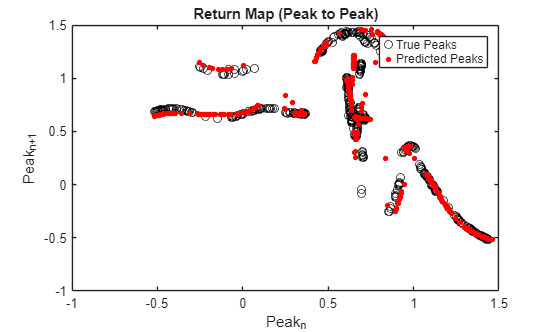

%% 7. Plot Phase Portraits After Training
figure('Name','Phase Portrait Comparison');
if size(xTrue,2) > 1
    %plot(xTestTrue(:,1), xTestTrue(:,2), 'k', 'LineWidth',1); hold on;
    plot(xPred(:,1),       xPred(:,2),       'r--','LineWidth',1);
    hold off; legend('True','Predicted');
    title('Phase Portrait (Channels 1 vs 2)'); xlabel('x_1'); ylabel('x_2');
else
    embTrue = [xTestTrue(1:end-1), xTestTrue(2:end)];
    embPred = [xPred(1:end-1),       xPred(2:end)];
    plot(embTrue(:,1), embTrue(:,2), 'k', 'LineWidth',1); hold on;
    plot(embPred(:,1), embPred(:,2), 'r--','LineWidth',1); hold off;
    legend('True','Predicted');
    title('2D Delay Embedding'); xlabel('x(t)'); ylabel('x(t+1)');
end

%% 8. Return Map (Peak-to-Peak) Plot
[pTrue, ~] = findpeaks(xTestTrue(:,min(3,end)));
[pPred, ~] = findpeaks(xPred(:,min(3,end)));
figure('Name','Return Map');
plot(pTrue(1:end-1), pTrue(2:end), 'ko','MarkerSize',6); hold on;
plot(pPred(1:end-1), pPred(2:end), 'r.','MarkerSize',12); hold off;
legend('True Peaks','Predicted Peaks');
title('Return Map (Peak to Peak)'); xlabel('Peak_n'); ylabel('Peak_{n+1}');
drawnow;
save(strcat(dynamicsName,'_network.mat'),'net','trainingInfo','-v7.3');
end